clear
T = readtable("g_edges.csv",'FileType',"text");
T_names = readtable("g_nodes.csv",'FileType',"text");
G = digraph(T.Source,T.Target,T.Weight);
G.Nodes.NodeSizes = 2.*sqrt(indegree(G)-min(indegree(G))+0.2);
p = plot(G,"Layout","auto");
p.MarkerSize = G.Nodes.NodeSizes;

colormap('jet');
G.Nodes.NodeColors = 2.*sqrt(indegree(G)-min(indegree(G))+0.2);
p.NodeCData = G.Nodes.NodeColors;
colorbar

shortPath = shortestpath(G,'NED','TYRION');
disp("Самый короткий путь от NED к TYRION:")

Самый короткий путь от NED к TYRION:


disp(shortPath)

    {'NED'}    {'PYP'}    {'TYRION'}



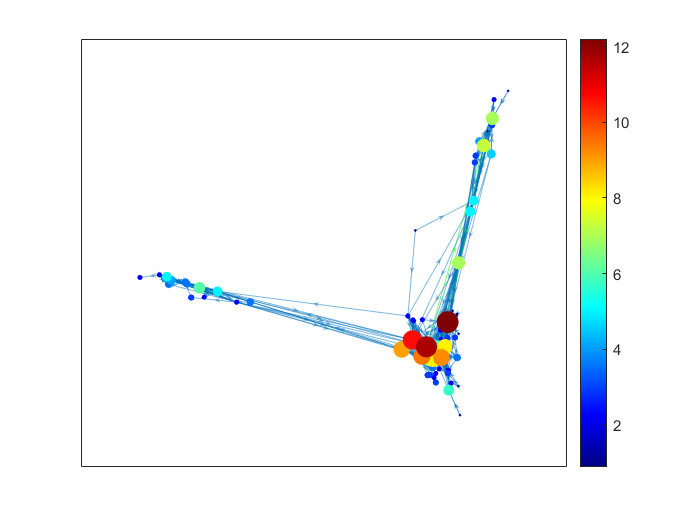

highlight(p,shortPath,"EdgeColor","green")


disp("ТОП5:")

ТОП5:


T1 = table(G.Nodes.Name, G.Nodes.NodeSizes);
T1 = sortrows(T1,"Var2","descend");
disp(head(T1,5))

       Var1        Var2 
    __________    ______

    {'TYRION'}    12.198
    {'NED'   }    11.696
    {'ROBERT'}    10.621
    {'SANSA' }    9.4234
    {'ROBB'  }    9.2087

